# Statistics and Data Analysis in Neuroscience:  Probability Theory

During this session, we will focus on the branch of mathematics that is concerned with the analysis of random phenomena, based on the theories developed by [Blaise Pascal](https://en.wikipedia.org/wiki/Blaise_Pascal) and [Thomas Bayes](https://en.wikipedia.org/wiki/Thomas_Bayes). 

In probability theory, the random variables are often written in upper case roman letters, such as X, Y, A, B. Particular realizations of a random variable are written in lower case etters, such as x, x1, xn. The capital letter P refers to the probability. 

To recap some mathematical principles: 

- a mathematical [set](https://en.wikipedia.org/wiki/Set_(mathematics)) is a well-defined collection of a group of objects. 

- an [axiom](http://mathworld.wolfram.com/Axiom.html) is a proposition regarded as self-evidently true without proof. 

- a [theorem](http://mathworld.wolfram.com/Theorem.html) is a statement that can be demonstrated to be true by accepted mathematical operations. Therefore, a theorem is a statement based on axioms.

In probability theory, the theorems of a mathematical set looks like:


$$P(A \cap B)  \text{ :indicates the probability that events A and B both occur.}\\
P(A \cup B) \text{ :indicates the probability of either event A or event B occurring.}$$


And the following assumptions are used: 

- 
$$P(X)  \ge 0
$$


- 
$$P(A||) = 1
$$


- 
$$P(A \cup B) = P(A) + P(B)\\
\text{if } A \cap B = 0 
$$


## Conditional Probability 

 A [Conditional Probability](https://en.wikipedia.org/wiki/Conditional_probability) is a measure of the probability of an event given that another event has occurred. This is written as:


$$P(X | Y) = \frac{P(X \cap Y)}{P(Y)}$$


Therefore a **Joint Probability **(more info [here](https://en.wikipedia.org/wiki/Joint_probability_distribution)) is written as:


$$P(X \cap Y) = P(X | Y) * P(Y)$$


In addition, you should take into account the concept of **independence**:


$$P(X | Y) = P(X),$$


meaning that X is independent from Y. 

Therefore, the joint probability will become


$$P(X \cap Y) = P(X) * P(Y)$$


Here we start with start with a simple simulation to visualize the importance of independence in conditional probability. First of all we plot a random scatter plot:

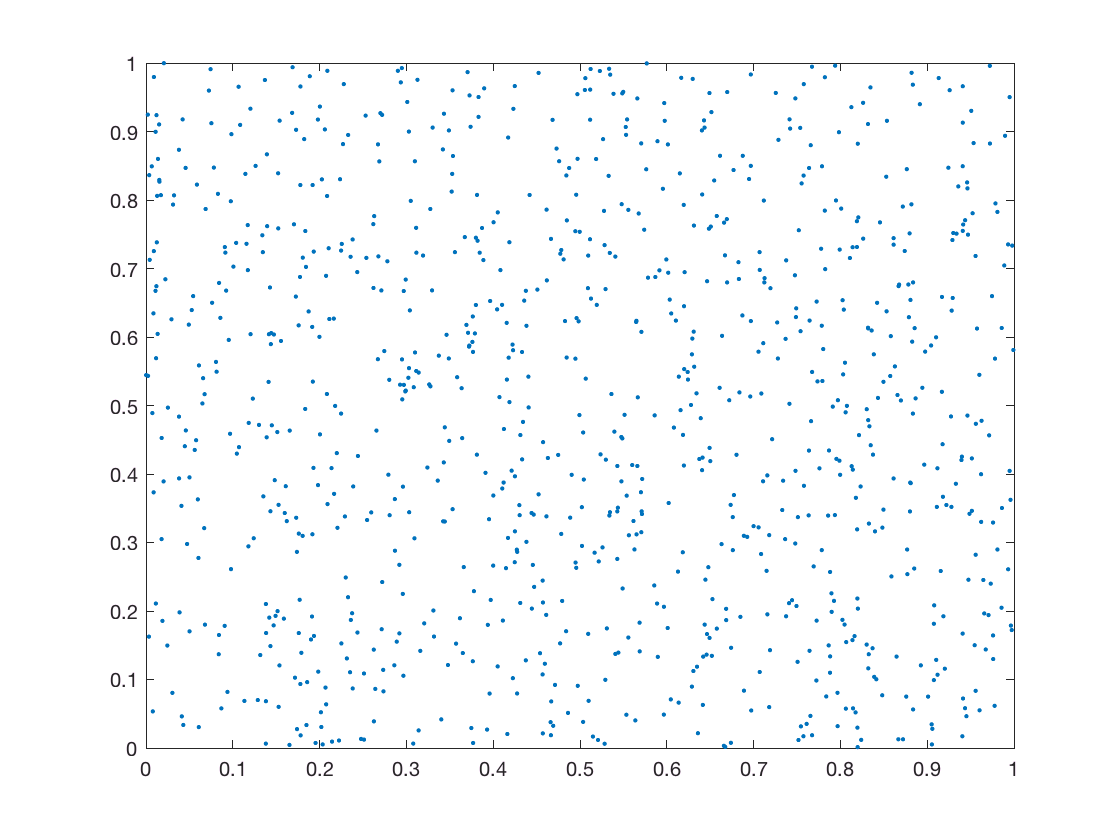

x = rand(1,1000);
y = rand(1,1000);
plot(x,y, '.')

We will create a 2x2 [contingency table](https://en.wikipedia.org/wiki/Contingency_table), which is a type of table in a matrix that displays the frequency distribution of the variables.

a = sum(x<0.5 & y<0.5)

a =    268


b = sum(x<0.5 & y>0.5)

b =    255


c = sum(x>0.5 & y<0.5)

c =    247


d = sum(x>0.5 & y>0.5)

d =    230


C = {a,c;b,d};
T = cell2table(C, ...
    'VariableNames',{'x_left','x_right'})

T =     x_left    x_right
    ______    _______

    268       247    
    255       230    


## Bayesian Theorem

The [Bayesian Theorem](https://en.wikipedia.org/wiki/Bayes'_theorem) describes the probability of an event, such that


$$P(Y | X) = \frac{P(X \cap Y)}{P(X)}$$


## Cumilitative Distribution

The [cumulative distribution ](https://en.wikipedia.org/wiki/Cumulative_distribution_function)of a real-valued random variable evaluated at *x*, is the probability that *X* will take a value less than or equal to *x,*


$$F(x) = P(X \le x)$$


In MatLab, you can use the function *normcdf *("help normcdf" for more information) to generate a Normal Cumulative Distribution.

format longg
norm1 = normcdf(1,0,1);
norm1

norm1 =          0.841344746068543


format longg
norm2 = normcdf(1,0,1)-normcdf(-1,0,1);
norm2

norm2 =          0.682689492137086


x = randn(1,1000000);
hist(x,1000)
format long
mean(abs(x)<1)

ans =    0.682371000000000


Using the the **law of large numbers **(which is a principle of probability according to which the frequencies of events with the same likelihood of occurrence even out, given enough trials or instances), you will see that using more numbers, the mean gets more precise.

tic
mean(abs(randn(1,10^9))<1)
toc

If you like to see what happens when you change the amount and value of the parameters in probability distributions, you can use these tools in MatLab to play around:

- randtool

- disttool

## Binomial Probability

The [binomial probability](https://en.wikipedia.org/wiki/Binomial_distribution) uses the parameters *n* and *p* to determine the number of successes in a sequence of *n* independent binomial (such as yes/no) experiments. Each *n * has a success probability of *p*. An example of a binomial distribution is flipping a coin, where 


$$P(head) = P(tail) = \frac{1}{2}$$


In MatLab, you can use the "binocdf(x,n,p)" command (see "help binocdf") where the input is x, *n* and probability *p*. 

--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## Expected value 'E'

The [Expected value E](https://en.wikipedia.org/wiki/Expected_value) of a random variable, where you assume that you have a cumulative distribution


$$\int_{-\infty}^{\infty} x f(x) dx$$
